%CLEAR THE WORKSPACE

clear all;
clc

Vr = 0.010:0.001:0.310;
Tr = 0:0.001:1;

%PARAMETERS [f,B1,B2,b1,b3,B3]

param = [0.85, 0.143, 0.06, 0.143, 0.05, 0.05];

%TIME INTERVAL AND INITIAL CONDITIONS

%16 weeks in semester, 7 days a week, 
tspan = 0:0.1:112;
init_cond1 = [0.99 .01 0 0 0]';

%0.22=VR low    0.5 or 1 for VR high

mSS_fin_vals = mSS_func(Vr, Tr, param, init_cond1, tspan)

mSS_fin_vals =     0.0100    0.0110    0.0120    0.0130    0.0140    0.0150    0.0160    0.0170    0.0180    0.0190    0.0200    0.0210    0.0220    0.0230    0.0240    0.0250    0.0260    0.0270    0.0280    0.0290    0.0300    0.0310    0.0320    0.0330    0.0340    0.0350    0.0360    0.0370    0.0380    0.0390    0.0400    0.0410    0.0420    0.0430    0.0440    0.0450    0.0460    0.0470    0.0480    0.0490    0.0500    0.0510    0.0520    0.0530    0.0540    0.0550    0.0560    0.0570    0.0580    0.0590
    0.0020    0.0030    0.0080    0.0100    0.0100    0.0100    0.0100    0.0170    0.0170    0.0170    0.0170    0.0170    0.0170    0.0170    0.0170    0.0170    0.0170    0.0170    0.0170    0.0170    0.0170    0.0170    0.0170    0.0170    0.0170    0.0170    0.0170    0.0170    0.0170    0.0170    0.0170    0.0170    0.0170    0.0170    0.0170    0.0170    0.0170    0.0170    0.0170    0.0170    0.0170    0.0170    0.0170    0.0170    0.0170    0.0170    0.0170    0.0170    


oneSS_fin_vals = oneSS_func(Vr, Tr, param, init_cond1, tspan)

oneSS_fin_vals =     0.0100    0.0110    0.0120    0.0130    0.0140    0.0150    0.0160    0.0170    0.0180    0.0190    0.0200    0.0210    0.0220    0.0230    0.0240    0.0250    0.0260    0.0270    0.0280    0.0290    0.0300    0.0310    0.0320    0.0330    0.0340    0.0350    0.0360    0.0370    0.0380    0.0390    0.0400    0.0410    0.0420    0.0430    0.0440    0.0450    0.0460    0.0470    0.0480    0.0490    0.0500    0.0510    0.0520    0.0530    0.0540    0.0550    0.0560    0.0570    0.0580    0.0590
    0.1030    0.1030    0.1040    0.1040    0.1040    0.1040    0.1040    0.1040    0.1040    0.1040    0.1040    0.1040    0.1040    0.1040    0.1040    0.1040    0.1040    0.1040    0.1050    0.1050    0.1050    0.1050    0.1050    0.1050    0.1050    0.1050    0.1050    0.1050    0.1050    0.1050    0.1050    0.1050    0.1060    0.1060    0.1060    0.1060    0.1060    0.1060    0.1060    0.1060    0.1060    0.1060    0.1060    0.1060    0.1060    0.1060    0.1060    0.1060  


noSS_fin_vals = noSS_func(Vr, Tr, param, init_cond1, tspan)

noSS_fin_vals =     0.0100    0.0110    0.0120    0.0130    0.0140    0.0150    0.0160    0.0170    0.0180    0.0190    0.0200    0.0210    0.0220    0.0230    0.0240    0.0250    0.0260    0.0270    0.0280    0.0290    0.0300    0.0310    0.0320    0.0330    0.0340    0.0350    0.0360    0.0370    0.0380    0.0390    0.0400    0.0410    0.0420    0.0430    0.0440    0.0450    0.0460    0.0470    0.0480    0.0490    0.0500    0.0510    0.0520    0.0530    0.0540    0.0550    0.0560    0.0570    0.0580    0.0590
    0.1170    0.1170    0.1170    0.1170    0.1170    0.1170    0.1170    0.1170    0.1170    0.1170    0.1170    0.1170    0.1170    0.1170    0.1170    0.1170    0.1170    0.1170    0.1170    0.1170    0.1170    0.1170    0.1170    0.1170    0.1170    0.1170    0.1170    0.1170    0.1170    0.1170    0.1170    0.1170    0.1170    0.1170    0.1170    0.1170    0.1170    0.1170    0.1170    0.1170    0.1170    0.1170    0.1170    0.1170    0.1170    0.1170    0.1170    0.1170   

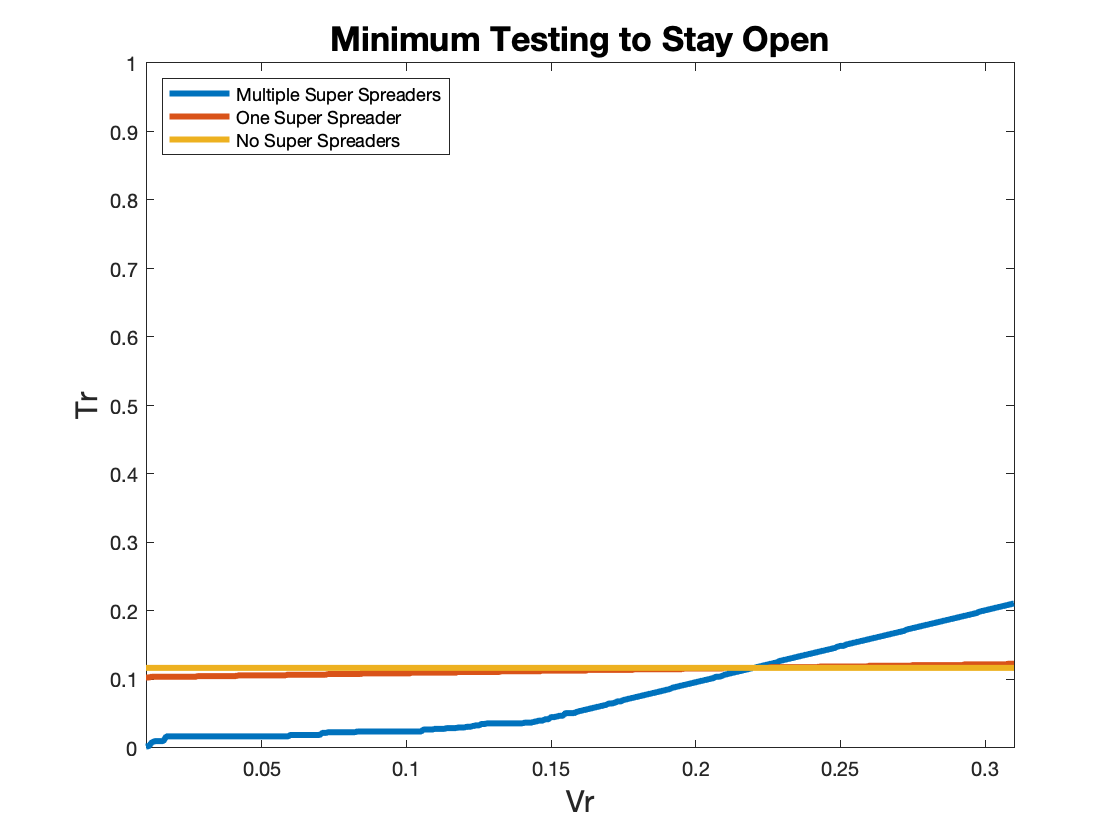

%Plotting Data

figure

plot(mSS_fin_vals(1,:),mSS_fin_vals(2,:), "LineWidth", 3)
hold on
plot(oneSS_fin_vals(1,:),oneSS_fin_vals(2,:), "LineWidth", 3)
hold on
plot(noSS_fin_vals(1,:),noSS_fin_vals(2,:), "LineWidth", 3)

legend("Multiple Super Spreaders","One Super Spreader", "No Super Spreaders",'Location','northwest');
title("Minimum Testing to Stay Open", 'FontSize', 17);
ylabel("Tr", "FontSize", 15);
xlabel("Vr", "FontSize", 15);
xlim([0.01 .31])
ylim([0 1])